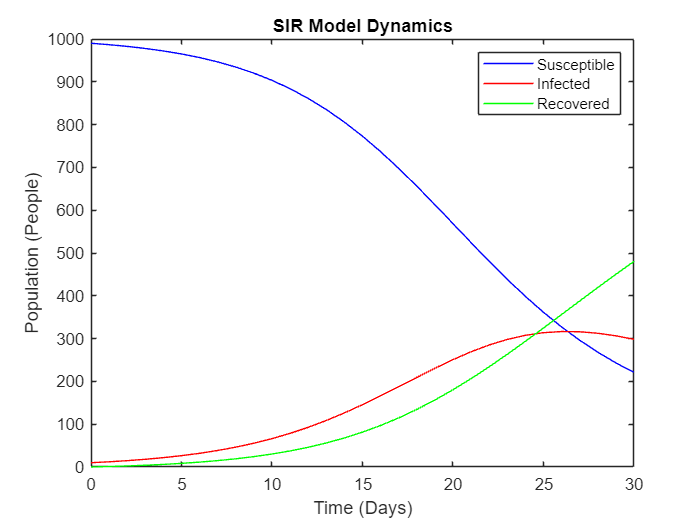

% Group Project Part 3: Least-Squares Regression.
% Initial Conditions and Necessary Equations for Step 1.
S(1) = 990;                     % Initial susceptible population.
I(1) = 10;                      % Initial infected population.
R(1) = 0;                       % Initial recovered population.
N = 1000;                       % Total population.
B = 0.3;                        % Transmition rate.
Y = 0.1;                        % Recovery rate.
h = 1;                          % Time step.
t = 0:h:30;                     % Simulation duration.
dS = @(S,I)(-B*S*I/N);          % Given ODE for S(t).
dI = @(S,I)((B*S*I/N)-(Y*I));   % Given ODE for I(t).
dR = @(I)(Y*I);                 % Given ODE for R(t).
% Loop that determines the values of S(t), I(t), and R(t) using the given
% initial values and the fourth-order Runge-Kutta Method for each day.
for x = 1:(length(t)-1)
    K1S = dS(S(x),I(x));
    K1I = dI(S(x),I(x));
    K1R = dR(I(x));
    K2S = dS(S(x)+(h/2),I(x)+(K1I*h/2));
    K2I = dI(S(x)+(h/2),I(x)+(K1I*h/2));
    K2R = dR(I(x)+(K1I*h/2));
    K3S = dS(S(x)+(h/2),I(x)+(K2I*h/2));
    K3I = dI(S(x)+(h/2),I(x)+(K2I*h/2));
    K3R = dR(I(x)+(K2I*h/2));
    K4S = dS(S(x)+h,I(x)+(K3I*h));
    K4I = dI(S(x)+h,I(x)+(K3I*h));
    K4R = dR(I(x)+(K3I*h));
    S(x+1) = S(x)+((K1S+(2*K2S)+(2*K3S)+K4S)*h/6);
    I(x+1) = I(x)+((K1I+(2*K2I)+(2*K3I)+K4I)*h/6);
    R(x+1) = R(x)+((K1R+(2*K2R)+(2*K3R)+K4R)*h/6);
end
% Plots the values of S(t), I(t), and R(t) determined in the loop above.
figure(1)
plot(t,S,'b',t,I,'r',t,R,'g')
xlabel('Time (Days)')
ylabel('Population (People)')
title('SIR Model Dynamics')
legend('Susceptible','Infected','Recovered')

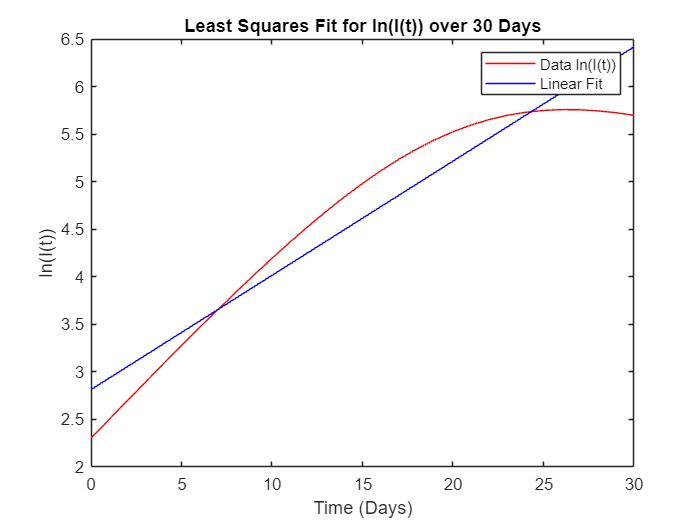

% Initial Conditions and Necessary Equations for Step 2.
n = length(t);
u = sum(t);
w = sum(t.^2);
lnI = log(I);
y = sum(lnI);
z = sum(t.*lnI);
k = ((n*z)-(u*y))/((n*w)-(u^2));
lnI0 = (y-(k*u))/n;
I0 = exp(lnI0);
B1 = ((k+Y)*N)/S(1);
% Plots the analytical solution, I(t) = I(0)e^kt, over 30 days.
figure(2)
plot(t,lnI,'r',t,lnI0+(k*t),'b')
xlabel('Time (Days)')
ylabel('ln(I(t))')
title('Least Squares Fit for ln(I(t)) over 30 Days')
legend('Data ln(I(t))','Linear Fit')

% Displays the estimated values for I(0), k, and beta over 30 days.
disp("Requested information for Step 2.")

Requested information for Step 2.


disp("Estimated I(0) over 30 Days: " + I0)

Estimated I(0) over 30 Days: 16.6724


disp("Estimated k over 30 Days: " + k)

Estimated k over 30 Days: 0.12012


disp("Estimated beta over 30 Days: " + B1)

Estimated beta over 30 Days: 0.22235


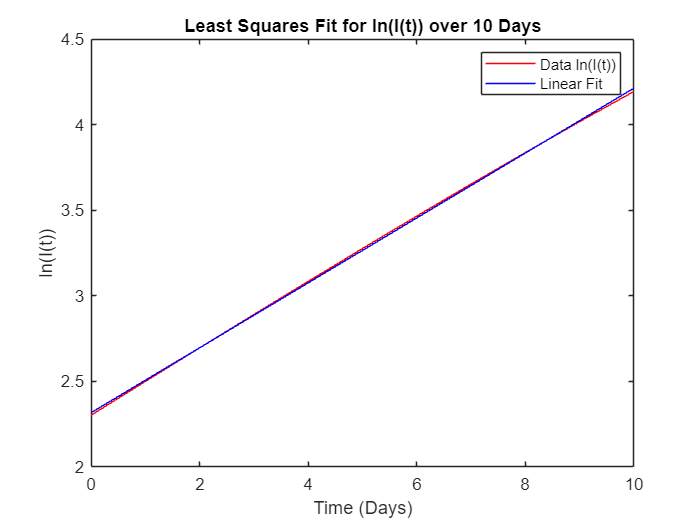

% Initial Conditions and Necessary Equations for Step 3.
d = t(1:11);
m = length(d);
b = sum(d);
c = sum(d.^2);
J = I(1:11);
lnJ = log(J);
e = sum(lnJ);
f = sum(d.*lnJ);
l = ((m*f)-(b*e))/((m*c)-(b^2));
lnJ0 = (e-(l*b))/m;
J0 = exp(lnJ0);
B2 = ((l+Y)*N)/S(1);
% Plots the analytical solution, I(t) = I(0)e^(kt), over 10 days.
figure(3)
plot(d,lnJ,'r',d,lnJ0+(l*d),'b')
xlabel('Time (Days)')
ylabel('ln(I(t))')
title('Least Squares Fit for ln(I(t)) over 10 Days')
legend('Data ln(I(t))','Linear Fit')

% Displays the estimated values of I(0), k, and beta over 10 days.
disp("Requested information for Step 3.")

Requested information for Step 3.


disp("Estimated I(0) over 10 Days: " + J0)

Estimated I(0) over 10 Days: 10.1468


disp("Estimated k over 10 Days: " + l)

Estimated k over 10 Days: 0.1896


disp("Estimated beta over 10 Days: " + B2)

Estimated beta over 10 Days: 0.29252


As can be seen from the graphs of lnI(t) and the estimated values of I(0), k, and beta, reducing the number of days to 10 results in a significant increase in the accuracy of said values. By using fewer sets of data, the model becomes more linear, meaning a line can be fit to the data much more accurately compared to using more data points. Hence the values of I(t), k, and beta being much more accurate with 10 days of data instead of the full 30 days of data.